% ============================================= PROJECT OVERVIEW ================================================================== %

%{

Author: Lucina Kerrigan
Student Number: B00803606
Last Updated: 06 Apr 2025

OVERVIEW
A comparison of two neural network classifiers using the [name of dataset
here] dataset. This project integrates the anaconda python environment into MatLab to
enable usage of python's ML/data-science libraries. 

Please ensure your Python version is at least 3.12. 

WINDOWS USERS: PLEASE ENSURE YOU ADD YOUR ANACONDA PYTHON PATH IN PLACE OF THE COMMENT ON LINE []. 
THIS IS SO THE PROGRAM KNOWS WHERE YOUR PYTHON EXE IS. 

REQUIRED LIBRARIES/ADDONS:
scikit-learn 1.6.1
numpy 1.26.4
SimBiology (MATLAB Addon). 

Other versions of these libraries probably work but in my foolish mortal
hubris, I attempted to install newer versions of these which resulted in a
universe of torment and despair. The Anaconda command line is now forever
burned into my eyes and my brain itself. It shall haunt my waking
nightmares and follow me to my grave. After realising that I had committed
an act against God, I repented my sins and reverted the library versions
back to what I had before, and I shan't touch them again. I have learned a
grave yet valuable lesson this day. 

%}

% ================================================================================================================================ %

% ========================================= PYTHON PATH & LIBRARY CHECKS ========================================================= %

% since this project exists across multiple computers, create checks
% to determine which path it is currently in

if ispc % Windows
    % Anaconda locations for both my computers
    possible_paths = {
        'C:\Users\Luci\anaconda3\python.exe', ...machine A's path
        'C:\Users\User\anaconda3\python.exe', ...machine B's path
        % WINDOWS USERS: ADD YOUR ANACONDA PYTHON PATH HERE, SAVE, AND RESTART MATLAB
        % If using the base environment, your path is:
        % C:\Users\[username]\anaconda3\python.exe
        };

    % find the first valid path
    for i = 1:length(possible_paths)
        if isfile(possible_paths{i})
            pyenv('Version', possible_paths{i});
            disp(['Python set to: ' possible_paths{i}])
            break;
        end
    end

else % Mac/Linux
    pyenv('Version', '~/anaconda3/bin/python');
end

Python set to: C:\Users\User\anaconda3\python.exe



% check if sci-kit learn is available
try
    py.importlib.import_module('sklearn');
    disp('Python integration working!');
catch
    disp('Error importing sklearn - check Python environment');
end

Python integration working!



% ================================================================================================================================ %

% ========================================= DATA LOADING & VISUALISATION ========================================================= %

data = readtable('wdbc.data', 'FileType','text', 'ReadVariableNames', false);

% column headers obtained from dataset documentation
% for each header, we assign a Mean, Standard Error (SE), and a Worst
varNames = {'ID', 'Diagnosis', 'MeanRadius', 'MeanTexture', 'MeanPerimeter', 'MeanArea', ...
    'MeanSmoothness', 'MeanCompactness', 'MeanConcavity', 'MeanConcavePoints', ...
    'MeanSymmetry', 'MeanFractalDimension', 'SERadius', 'SETexture', 'SEPerimeter', ...
    'SEArea', 'SESmoothness', 'SECompactness', 'SEConcavity', 'SEConcavePoints', ...
    'SESymmetry', 'SEFractalDimension', 'WorstRadius', 'WorstTexture', ...
    'WorstPerimeter', 'WorstArea', 'WorstSmoothness', 'WorstCompactness', ...
    'WorstConcavity', 'WorstConcavePoints', 'WorstSymmetry', 'WorstFractalDimension'};

data.Properties.VariableNames = varNames; % replace default column names in table with custom names

% basic data overview
summary(data)


data: 569×32 table

Variables:

    ID: double
    Diagnosis: cell array of character vectors
    MeanRadius: double
    MeanTexture: double
    MeanPerimeter: double
    MeanArea: double
    MeanSmoothness: double
    MeanCompactness: double
    MeanConcavity: double
    MeanConcavePoints: double
    MeanSymmetry: double
    MeanFractalDimension: double
    SERadius: double
    SETexture: double
    SEPerimeter: double
    SEArea: double
    SESmoothness: double
    SECompactness: double
    SEConcavity: double
    SEConcavePoints: double
    SESymmetry: double
    SEFractalDimension: double
    

disp(['Total samples: ', num2str(height(data))])

Total samples: 569


ratio = sum(strcmp(data.Diagnosis, 'M')) / height(data) * 100;
disp(['Malignant/Benign ratio: ', num2str(ratio, '%.1f'), '%'])

Malignant/Benign ratio: 37.3%


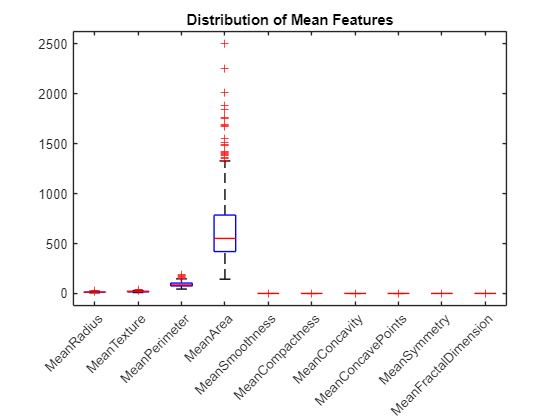


% Conclusion:
% The dimensions of the dataset are 569x32
% No values appear to be missing 
% There is a distinct class imbalance present in the dataset - 37% of the data is malignant while the remaining 63% is benign. 

% boxplot for feature ranges
figure;
boxplot(data{:,3:12}); % first 10 mean features
xticklabels(varNames(3:12));
xtickangle(45);
title('Distribution of Mean Features');

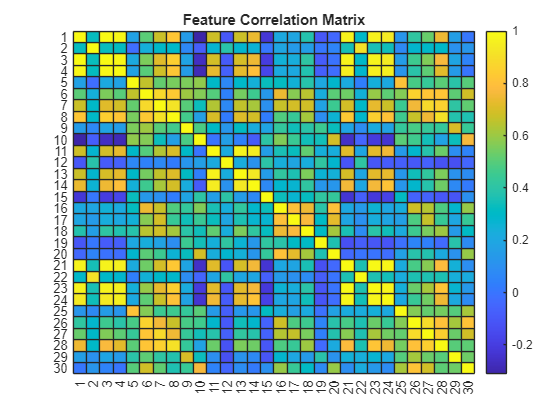


% feature correlation heatmap
corr_matrix = corr(data{:,3:end});
figure;
heatmap(corr_matrix, 'Colormap', parula);
title('Feature Correlation Matrix');


% z-score outlier detection
z_scores = zscore(data{:,3:end});
outliers = abs(z_scores) > 3;
disp(['Potential outliers: ', num2str(sum(outliers(:)))]) 

Potential outliers: 211


% nature of medical dataset and cancer specifically means i would rather
% keep outliers in the dataset, for now at least. 

% check for missing data
missing = sum(ismissing(data));
if any(missing)
    disp('Missing values found:')
    disp(varNames(missing > 0))
else
    disp('No missing values detected');
end

No missing values detected


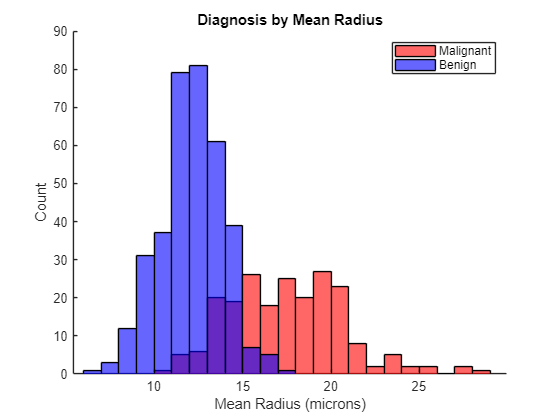


% feature distribution analysis
figure;
hold on;

histogram(data.MeanRadius(strcmp(data.Diagnosis, 'M')), 'BinWidth', 1, 'FaceColor', 'r');
histogram(data.MeanRadius(strcmp(data.Diagnosis, 'B')), 'BinWidth', 1, 'FaceColor', 'b');
legend('Malignant', 'Benign');
xlabel('Mean Radius (microns)');
ylabel('Count');
title('Diagnosis by Mean Radius'); % malignant tumours have larger radii


% ================================================================================================================================ %

% ============================================= PREPROCESSING ==================================================================== %

% define features and labels
features = double(data{:,3:end});
labels = double(strcmpi(data.Diagnosis, 'M'));

% converty to numpy arrays
features_py = py.numpy.array(features);

% explicitly ensure 2D shape
if isscalar(size(features_py))
    features_py = features_py.reshape(int32(size(features)))
end

labels_py = py.numpy.array(labels).reshape(int32(numel(labels))); % force 1D array shape

% create training and testing data

% execute the split in pure python to avoid data conversion errors
[~, pythonExe] = pyversion; % assign the variable "pythonExe" to the currently used python filepath

% save data to numpy files to be used by python script 
py.numpy.save('temp_features.npy', features_py);
py.numpy.save('temp_labels.npy', labels_py);

% file validation check for temp_features files (see 'checkFilesExist.m')
checkFilesExist({'temp_features.npy', 'temp_labels.npy'}, 'initial checks for py.numpy.save');

% standalone python script 
pyscript = [...
    'import numpy as np\n', ...
    'from sklearn.model_selection import train_test_split\n', ...
    'features = np.load("temp_features.npy")\n', ...
    'labels = np.load("temp_labels.npy")\n', ...
    'features_train, features_test, labels_train, labels_test = ' ...
        'train_test_split(features, labels, test_size=0.3, random_state=42)\n', ...
    'np.save("tr_X.npy", features_train)\n', ...
    'np.save("te_X.npy", features_test)\n', ...
    'np.save("tr_y.npy", labels_train)\n', ...
    'np.save("te_y.npy", labels_test)\n'];

% write to file and execute
fid = fopen('run_split.py', 'w');
fprintf(fid, pyscript);
fclose(fid);

% execute using the current Anaconda Python
system(['"', pythonExe, '" "', fullfile(pwd, 'run_split.py'), '"']);

% file validation check for training and testing npy files
checkFilesExist({'tr_X.npy', 'te_X.npy', 'tr_y.npy', 'te_y.npy'}, 'post train_test_split file checks');

% load results back
features_train = double(py.numpy.load('tr_X.npy')); % expected shape: [398 30]
features_test = double(py.numpy.load('te_X.npy')); % expected shape: [171 30]
labels_train = double(py.numpy.load('tr_y.npy')); % expected shape: [1 398]
labels_test = double(py.numpy.load('te_y.npy')); % expected shape [171 30]

% shapes of labels_train and labels_test have mismatched dimensions for
% some reason. this is a quick and dirty fix for that.
labels_train = labels_train(:);
labels_test = labels_test(:);

% file cleanup
filesForDeletion = {'temp_features.npy', 'temp_labels.npy', 'run_split.py', 'tr_X.npy', 'te_X.npy', 'tr_y.npy', 'te_y.npy'};
delete(filesForDeletion{:}); % unpacks cell array into comma separated list

% check for successful file deletion
for i = 1:length(filesForDeletion)
    if isfile(filesForDeletion{i})
        error('File was not deleted: %s', filesForDeletion{i})
    else
        fprintf('Confirmed deleted: %s\n', filesForDeletion{i})
    end
end

fprintf('All temporary files successfully deleted. \n')

% ========================================= SHALLOW NEURAL NETWORK ========================================================== %
%{ 
to-do:
shallow neural network

deep neural network

report 
%}


% ================================================================================================================================ %